# ADCS Project Part 2

Dillon Allen

#### Important Data from last time

clear, clc, close all;
orbital_rate      = 0.0010; % rad/s
period            = 6000;
wheel.maxTorque   = 0.025; % N-m
wheel.maxMomentum = 0.5; % N-m-s
wheel.maxSpeed    = 6000; % rpm
period = 6000;

% Spacecraft Inertia (Placeholder until Problem 13)
sc.Ix = 51;    % kg-m^2
sc.Iy = 253;   % kg-m^2
sc.Iz = 223.4; % kg-m^2


## Problem 13 

### Show spacecraft moment of inertias along the three axes are 51.0, 253.0, and 223.4 kg-m^2 respectively.

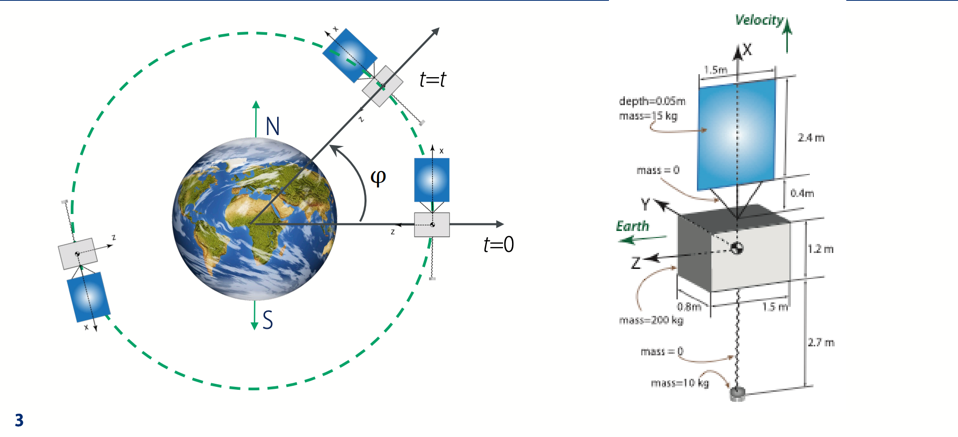

Calculating the inertias and applying parallel axis theorem, we have

% following the layout for the solution to pset 4
masses = [200 15 10];
dPanel = (1.2/2) + 0.4 + (2.4/2);
dPM = (1.2/2) + 2.7;
r_to_bc = [0 0 0; ...
           dPanel 0 0];
sizes = [1.2 0.8 1.5; ...
         2.4 0.05 1.5]

sizes =     1.2000    0.8000    1.5000
    2.4000    0.0500    1.5000


I_pm = [masses(3)*dPM^2 0 0; 0 0 0; 0 0 0];

I_syst = zeros(3,3);
for ii = 1:2
    Irect(:,:,ii) = [masses(ii)/12*(sizes(ii,2)^2 + sizes(ii,3)^2) 0 0;...
                     0 masses(ii)/12*(sizes(ii,3)^2 + sizes(ii,1)^2) 0;...
                     0 0 masses(ii)/12*(sizes(ii,1)^2 + sizes(ii,2)^2)];
    % Parallel Axis Theorem
    Irect(:,:,ii) = Irect(:,:,ii) + masses(ii)*[r_to_bc(ii,2)^2+r_to_bc(ii,3)^2 0 0;...
                                                0 r_to_bc(ii,1)^2+r_to_bc(ii,3)^2 0;...
                                                0 0 r_to_bc(ii,1)^2+r_to_bc(ii,2)^2];
    I_syst = Irect(:,:,ii) + I_syst;
end

I_syst = I_syst + I_pm;
I_syst

I_syst =   159.8823         0         0
         0  144.1125         0
         0         0  114.4698


## Problem 14

### Calculate the inertia of each wheel

We can calculate the inertia at max momenta, i.e

#### 
$$h_{max} = I_w \omega_{max}$$


wheel.maxSpeedrps = wheel.maxSpeed*(2*pi/1)*(1/60);
wheel.inertia = wheel.maxMomentum / wheel.maxSpeedrps;
fprintf("Wheel ineratia is: %f {kg-m^2}", wheel.inertia);

Wheel ineratia is: 0.000796 {kg-m^2}

## Problem 15

### Calculate the maximum spacecraft acceleration ($\dot{\omega}$) due to the wheel along each axis

To calculate this, we will use

#### 
$$I_x \dot{\omega}_x = T_{max}$$


sc.accelX = wheel.maxTorque / sc.Ix;
sc.accelY = wheel.maxTorque / sc.Iy;
sc.accelZ = wheel.maxTorque / sc.Iz;
fprintf("Spacecraft accelerations: (%f, %f, %f) {rad/s^2}", ...
    sc.accelX, sc.accelY, sc.accelZ);

Spacecraft accelerations: (0.000490, 0.000099, 0.000112) {rad/s^2}

## Problem 16

### What is the momentum needed to maintain nadir pointing?

Since nadir pointing is along the -Y axis, we will use the orbital rate times the inertia in the Y axis to see the momenta needed.

sc.nadirMomentum = sc.Iy * orbital_rate;
fprintf("Momentum needed for Nadir pointing: %f {N-m-s}", sc.nadirMomentum);

Momentum needed for Nadir pointing: 0.253000 {N-m-s}

## Problem 17

### What wheel speed would that level of momentum correspond to?

wheel.nadirSpeedrps = sc.nadirMomentum / wheel.inertia; % rad/s
wheel.nadirSpeed    = wheel.nadirSpeedrps * (1/(2*pi))*60;
fprintf("Wheel speed for nadir pointing: %f {rad/s}, %f {rpm}", ...
    wheel.nadirSpeedrps, wheel.nadirSpeed)

Wheel speed for nadir pointing: 317.929177 {rad/s}, 3036.000000 {rpm}

## Problem 18

### Find the PID gains for each axis, given parameters of $\omega_n = 0.5$(rad/s), $\zeta = 0.7$, $T = \frac{10}{\zeta \omega_n$ (s)

% Control parameters
K.omega_n = 0.5; % rad/s
K.zeta    = 0.7;
K.T       = 10/(K.omega_n * K.zeta); % seconds

% Gain Terms
p_term = K.omega_n^2 + (2*K.omega_n*K.zeta)/K.T;
i_term = K.omega_n^2 / K.T;
d_term = 2*K.omega_n*K.zeta + 1/K.T;

% Axis Gains
% X-AXIS
K.px = sc.Ix * p_term;
K.ix = sc.Ix * i_term;
K.dx = sc.Ix * d_term;

% Y-AXIS
K.py = sc.Iy * p_term;
K.iy = sc.Iy * i_term;
K.dy = sc.Iy * d_term;

% Z-AXIS
K.pz = sc.Iz * p_term;
K.iz = sc.Iz * i_term;
K.dz = sc.Iz * d_term;

fprintf("X-Axis gains")

X-Axis gains

fprintf("Kp: %f", K.px);

Kp: 13.999500

fprintf("Ki: %f", K.ix);

Ki: 0.446250

fprintf("Kd: %f", K.dx);

Kd: 37.485000

fprintf("Y-Axis gains")

Y-Axis gains

fprintf("Kp: %f", K.py);

Kp: 69.448500

fprintf("Ki: %f", K.iy);

Ki: 2.213750

fprintf("Kd: %f", K.dy);

Kd: 185.955000

fprintf("Z-Axis gains")

Z-Axis gains

fprintf("Kp: %f", K.pz);

Kp: 61.323300

fprintf("Ki: %f", K.iz);

Ki: 1.954750

fprintf("Kd: %f", K.dz);

Kd: 164.199000

## Problem 19

### Write the state space equations for each axis

% X - Axis
Ax = [0 1 0 0; ...
      0 0 1 0;...
     -K.ix/sc.Ix         -K.px/sc.Ix         -K.dx/sc.Ix          0; ...
      K.ix/wheel.inertia K.px/wheel.inertia K.dx/wheel.inertia  0];
Bx = [0; 0; 1/sc.Ix; 0];
Cx = [0 180/pi 0        0; ...
      0   0    0       30/pi; ...
      0   0    0   wheel.inertia];
Dx = zeros(3,1);

% Y - Axis
Ay = [0 1 0 0; ...
      0 0 1 0;...
     -K.iy/sc.Iy         -K.py/sc.Iy         -K.dy/sc.Iy          0; ...
      K.iy/wheel.inertia K.py/wheel.inertia K.dy/wheel.inertia  0];
By = [0; 0; 1/sc.Iy; 0];
Cy = [0 180/pi 0        0; ...
      0   0    0       30/pi; ...
      0   0    0   wheel.inertia];
Dy = zeros(3,1);

% Z - Axis
Az = [0 1 0 0; ...
      0 0 1 0;...
     -K.iz/sc.Iz         -K.pz/sc.Iz         -K.dz/sc.Iz          0; ...
      K.iz/wheel.inertia K.pz/wheel.inertia K.dz/wheel.inertia  0];
Bz = [0; 0; 1/sc.Iz; 0];
Cz = [0 180/pi 0        0; ...
      0   0    0       30/pi; ...
      0   0    0   wheel.inertia];
Dz = zeros(3,1);

## Problem 20

### Create a state-space transfer function for each axis

Gx = ss(Ax, Bx, Cx, Dx);
Gy = ss(Ay, By, Cy, Dy);
Gz = ss(Az, Bz, Cz, Dz);

## Problem 21

### Use lsim to plot the response along each axis

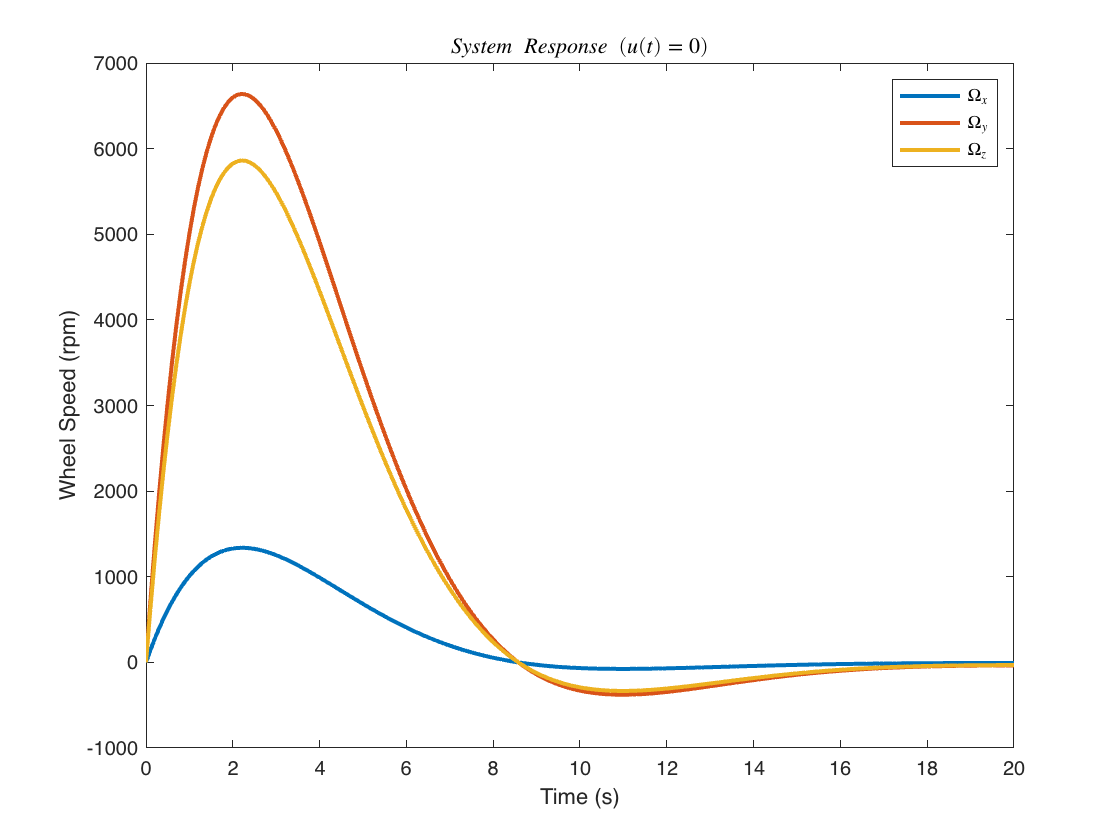

t = 0:0.1:20;
x0 = [0; deg2rad(0.5); 0; 0];
u = zeros(1,length(t));
x = lsim(Gx, u, t, x0);
y = lsim(Gy, u, t, x0);
z = lsim(Gz, u, t, x0);
plot(t,x(:,2), 'LineWidth',2)
hold on
plot(t,y(:,2), 'LineWidth',2)
plot(t,z(:,2), 'LineWidth',2)
xlabel("Time (s)");
ylabel("Wheel Speed (rpm)")
title("$System \ Response \ (u(t) = 0)$", 'Interpreter','latex');
legend("$\Omega_x$", "$\Omega_y$", "$\Omega_z$", 'Interpreter', 'latex')

## Problem 22

### Model the system response with the disturbances calculated earlier

% t_part2;

## Problem 23

### How long does it take to slew?

wheel.cappedSpeed = 4000 * (pi/30); % rad/s
t1 = (wheel.inertia * (wheel.cappedSpeed - 0))/wheel.maxTorque;
fprintf("Time to get to -4000 rpm: %f {sec}", t1);

Time to get to -4000 rpm: 13.333333 {sec}

thetaT1Slew = rad2deg(wheel.maxTorque/(2*sc.Iy)*t1^2);
dTheta = 90 - thetaT1Slew;
t2 = sqrt(2*sc.Iy*deg2rad(dTheta)/wheel.maxTorque);
totalTime = 2*(t1 + t2);
fprintf("Total time to slew 180 degrees: %f {sec}",totalTime);

Total time to slew 180 degrees: 382.279602 {sec}